% <<<<<<<<<<<<<<<<<<<< Line Coding Schemes >>>>>>>>>>>>>>>>>>>>
clc, clear all, close all;
% ******************* Digital/Binary input information ********************
% x = input('Enter Digital Input Information = ');   % Binary information as stream of bits (binary signal 0 or 1)
x = [1 0 1 0 0 0 1 1 0];
N = length(x);
Tb = 0.0001;   %Data rate = 1MHz i.e., bit period (second)
disp('Binary Input Information at Transmitter: ');

Binary Input Information at Transmitter: 


disp(x);

     1     0     1     0     0     0     1     1     0



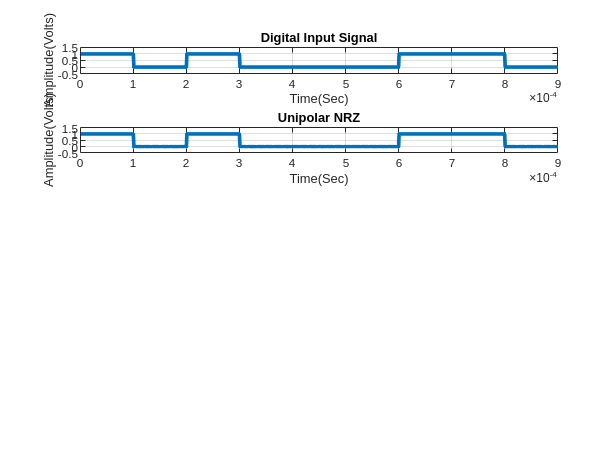

% ************* Represent input information as digital signal *************
nb = 100;   % Digital signal per bit
digit = []; 
for n = 1:1:N
    if x(n) == 1;
       sig = ones(1,nb);
    else x(n) == 0;
        sig = zeros(1,nb);
    end
     digit = [digit sig];
end
t1 = Tb/nb:Tb/nb:nb*N*(Tb/nb);   % Time period
figure('Name','Line Coding Schemes','NumberTitle','off');
subplot(5,1,1);
plot(t1,digit,'LineWidth',2.5);
grid on;
axis([0 Tb*N -0.5 1.5]);
xlabel('Time(Sec)');
ylabel('Amplitude(Volts)');
title('Digital Input Signal');
% ***************************** Unipolar NRZ ******************************
for i = 0:N-1
  if x(i+1) == 1
    Y(i*nb+1:(i+1)*nb) = 1;
  else
    Y(i*nb+1:(i+1)*nb) = 0;
  end
end
subplot(5,1,2)
plot(t1,Y,'LineWidth',2.5); grid on;
axis([0 Tb*N -0.5 1.5]);
xlabel('Time(Sec)');
ylabel('Amplitude(Volts)');
title(['Unipolar NRZ']);